# Exercise 2: Setup Estimation Filter to Track A Single Piece of Space Debris

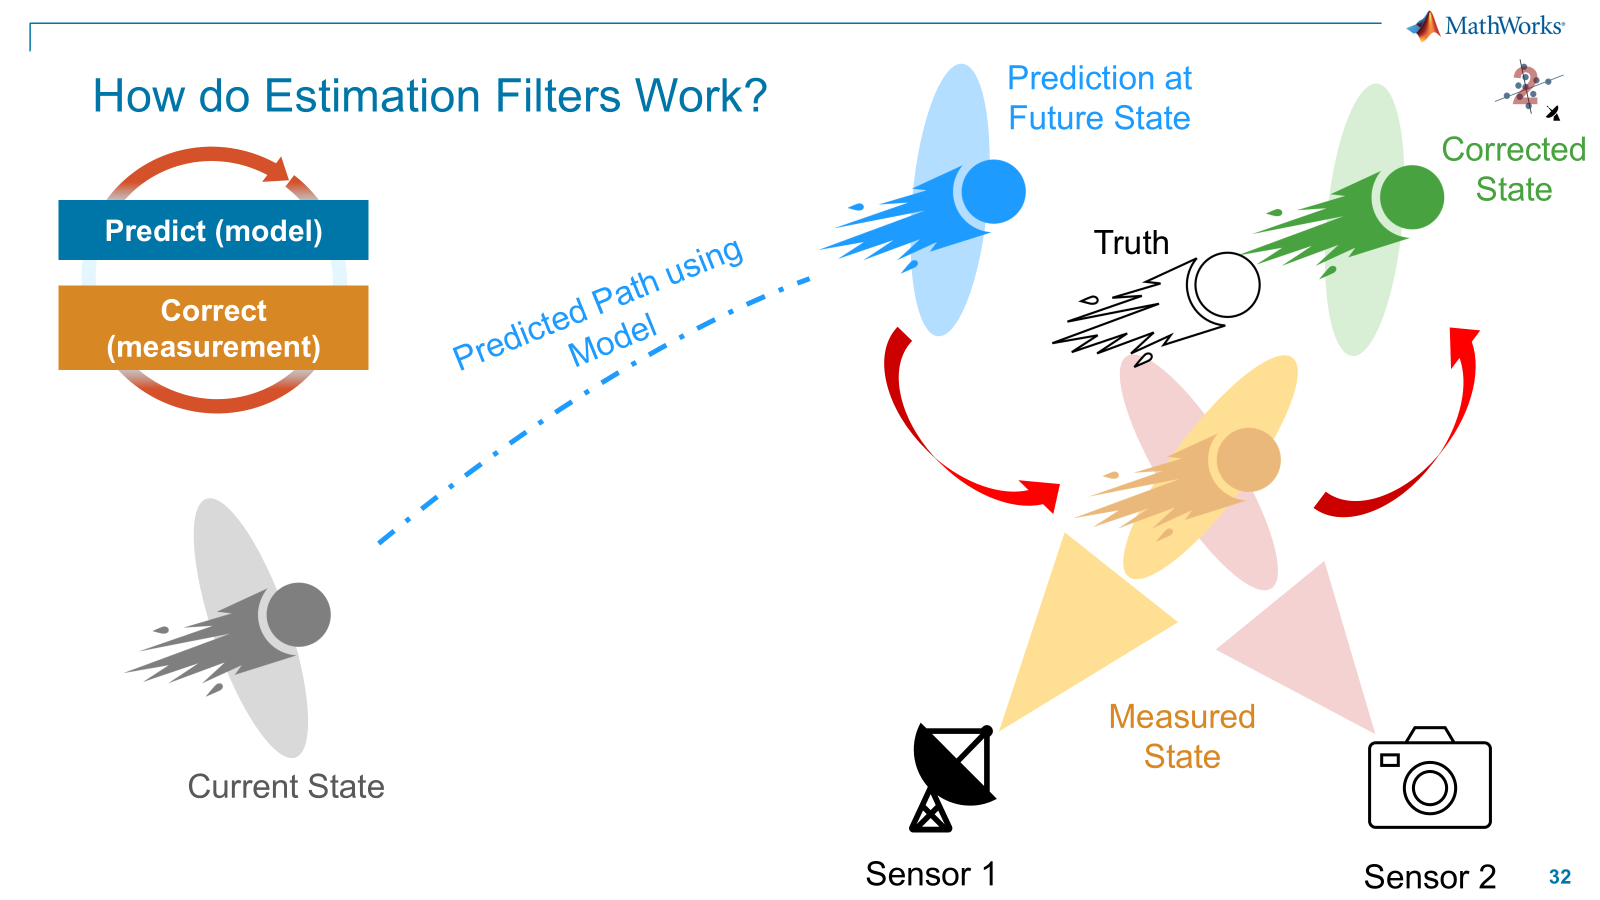

*Note: In the above diagram, we show two sensors, but for this exercise we are only using a single set of detections (implying a single sensor) for simplicity.*

When tracking space debris (or any target), estimation filters are commonly used to estimate the **state** of an object.  For tracking applications, a target's **state** commonly consists of some combination of position, velocity, and acceleration. Estimation filters leverage detections (often from sensor measurements), a motion model, and state update equation to predict and correct the future state of the system.

Generally, **Estimation Filters **capture the:

    1) Dynamics of the system via a prediction model (gives the **predicted state**), including the uncertainty of system dynamics (**process noise**) - these are used in the **prediction** step.

    2) Measurements (**detections**), including the uncertainty of the measurements (**measurement noise**) - these are used in the **correction** step.

For more information on state estimation filters, check this documentation page: [Introduction to Estimation Filters](https://www.mathworks.com/help/fusion/ug/introduction-to-estimation-filters.html). Especially, take a look at the flowchart at the bottom of the "Filter Design" section.

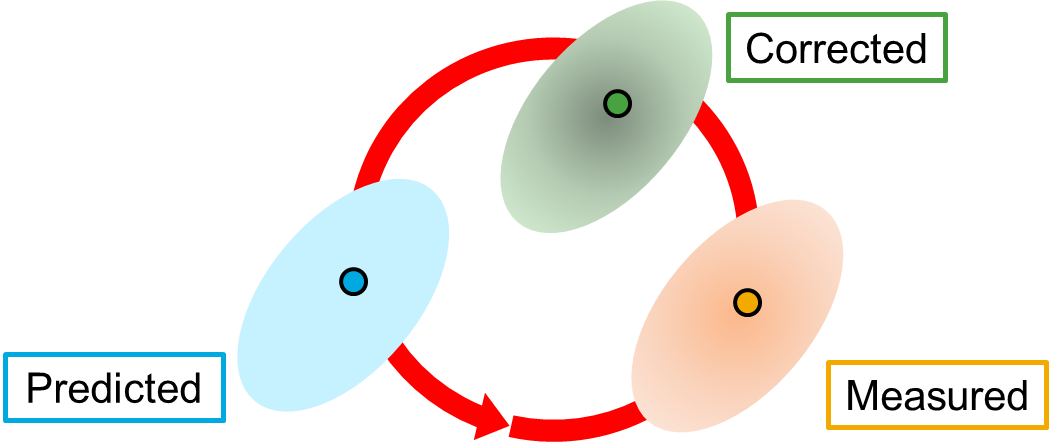

Filters take many forms, but one common filter is the **Extended Kalman Filter**, which we will use in this example. For more information on the Extended Kalman Filter, please check this documentation page: [Extended Kalman Filters.](https://www.mathworks.com/help/releases/R2024b/fusion/ug/extended-kalman-filters.html)

By using the default values for "trackingEKF" in Part 2a, we see that our predicted and corrected values are far from the true positions. Remember! These detections are space debris orbiting earth, so the path of the target is long, if our predictions and corrections don't appear exactly over the truth from this vantage point, they must be very far from the truth - on the order of 1e4 meters defined by the space between xticks and yticks on the plot above. We can see that our default filter is not well-tuned to the data. **But how bad is it?**

We can use the Mahalanobis Distance to estimate how accurate (or not!) our predicted and corrected positions are.  The Mahalanobis Distance is a measure between a sample point and a distribution, often used within trackers (more on that later). The calculation for the Mahalanobis Distance is within the helper function "plotMahalanobis" at the bottom of this script, if you are interested in the equation, please see [this documentation page](https://www.mathworks.com/help/releases/R2024b/stats/mahal.html?searchPort=58770#d126e790178).

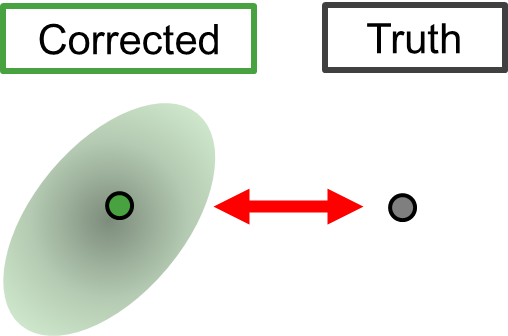

The Mahalanobis Distance is a value relative to a distribution, so a value of 1 means the value of interest (**corrected state**) is 1 standard deviation away from the base value (**truth** **state**).  We see that in our plot below, the **Mahalanobis Distances are very large**.

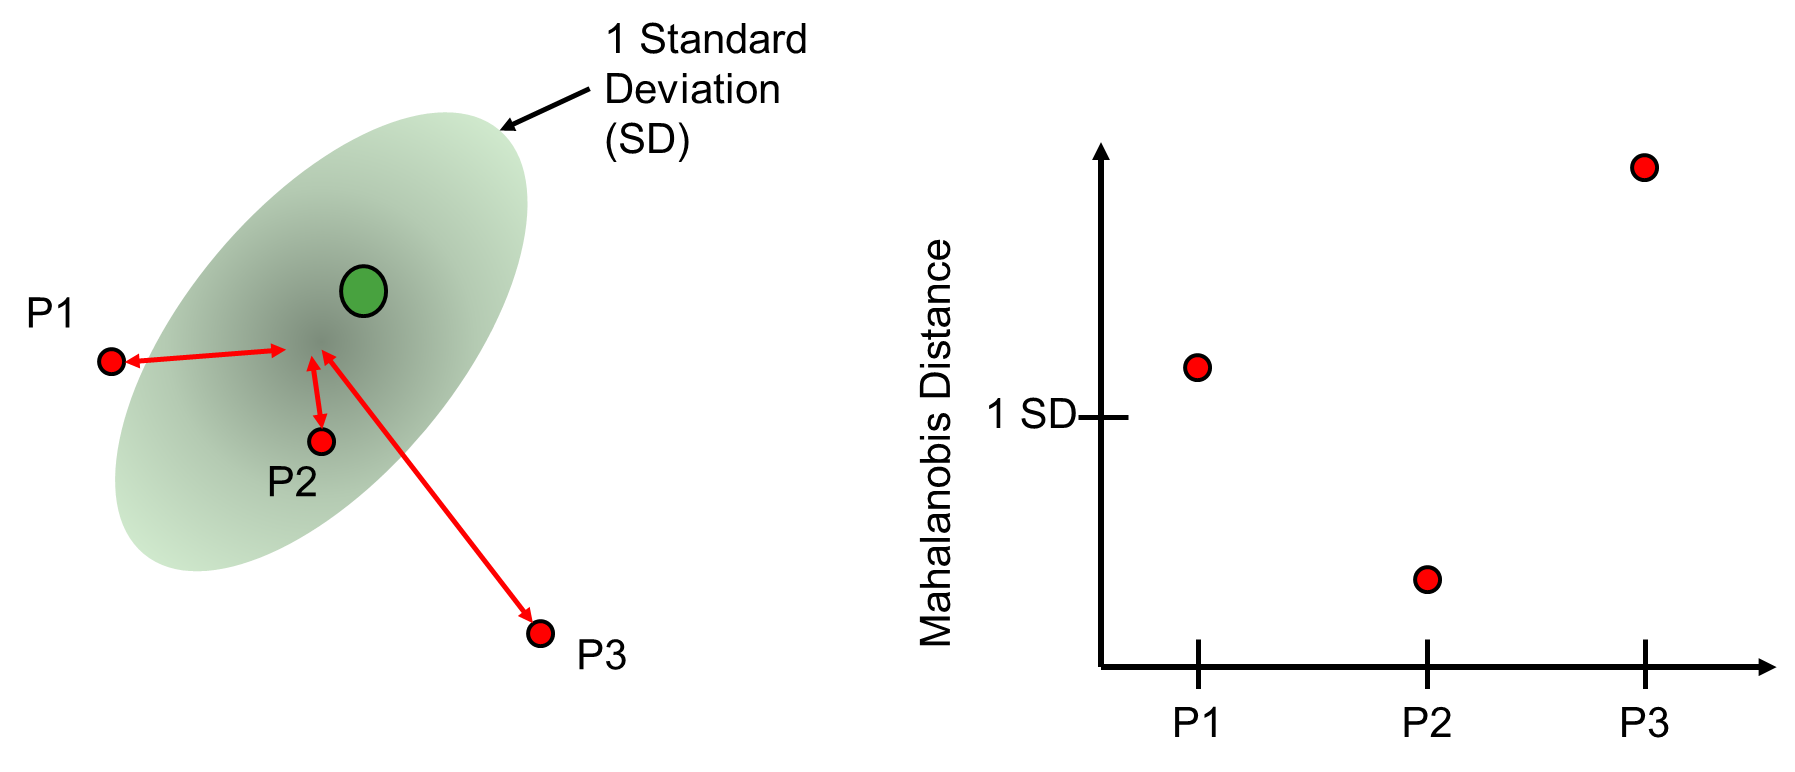

## Exercise 2a: State Estimation Using Default trackingEKF - Where will the debris be in one time step?

First, let's test how the default extended kalman filter performs on our dataset for a single piece of space debris.

We can clear our workspace and command window and also close all open figures with the commands below:

clear; clc; close all;

Let's load in our truth and detection data from the previous example:

S = load('SpaceDebrisLEO_1Target.mat');
truthPos = S.truthPos; % Truth Position - where the target actually is
detPos = S.detPos;     % Detection Position - where the target was detected
time = S.time;
objDet = S.objDet;
truthVel = S.truthVel;
speed = S.speed;
initialDetection = objDet{1};

Now, let's define a filter.

Coding Directions:

Define the estimation filter using a "trackingEKF" filter.  Please create a variable 'filter' that holds the default Extended Kalman Filter (EKF) estimation filter. (HINT: use the "trackingEKF")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER CODES THIS:
% type "doc trackingEKF" in the Command Window to find the documentation page for this function
filter = initctekf(initialDetection);
% This filter runs with default inputs
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Plot Detections, Predictions, and Corrections

Loop through the detection data via the time vector to plot detections, predictions, and corrections as the target moves through the space near the radar sensor.

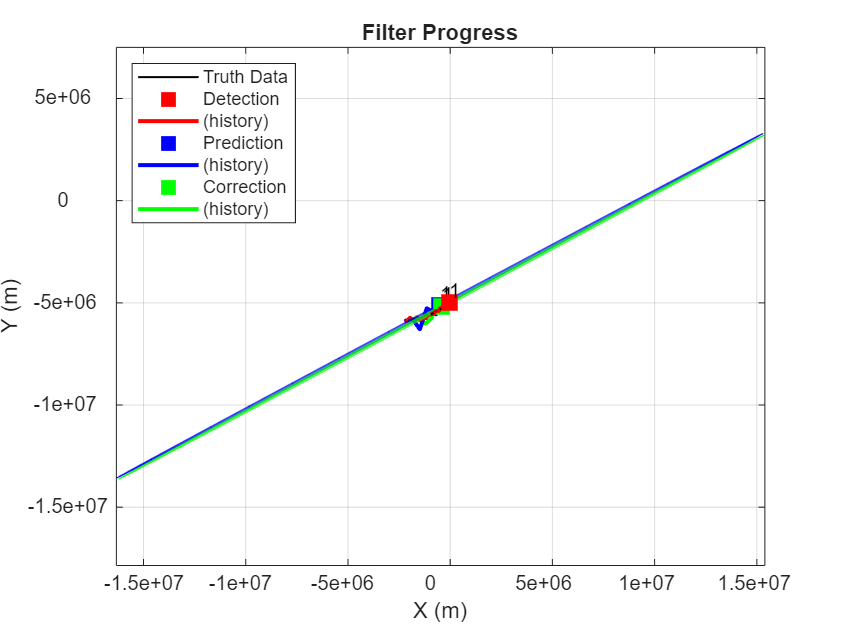

mahalanobisDist = helperRunDataLoop(detPos,truthPos,filter,time,objDet{1}.MeasurementNoise);

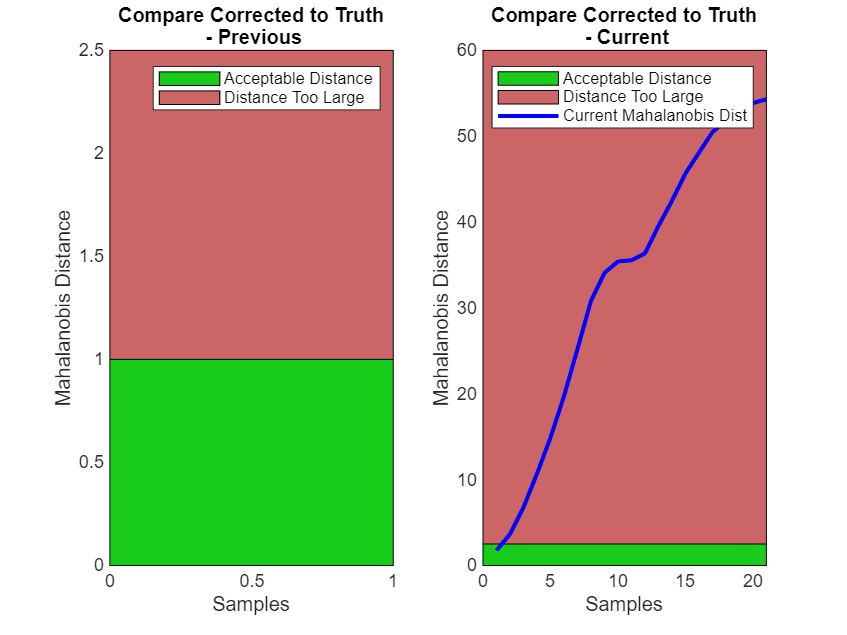

mahDist1  = plotMahalanobisDist(mahalanobisDist,[]);

## Exercise 2b: Improve State Estimation by Adjusting Filter (EKF) Settings 

## With the default trackingEKF settings, we see that our predicted and corrected values don't match our data.** What do we do now?**

To improve our filter, there are a few things we can do:

1) Improve our **initial estimate** of the system and the initial **state covariance** (or the confidence in that estimate).

        a) We can apply the initial detection as the initial state of our system, assuming zero velocity, and this should anchor our filter closer to the true initial state.

        b) Edit values within the **state covariance** matrix to better match the dynamics of the system.  In our constant velocity case, if the filter assumes the target moves slower than it does, the filter may have a tough time predicting the subsequent position of our target.

2) Adjust the **Measurement Noise **to match our detections. Clearly, from our Mahalanobis Distance measurement analysis above, we can tell that our measurements are far from the true positions.  In the 2D plot, we see that our corrected positions are close to the detection positions. Taken together, this suggests that we are not properly considering the measurement noise.  To incorporate the measurement of the detections, we can set the **Measurement Noise** of the filter to the same values as the **Measurement Noise** of the detections.

3) Adjust the **Process Noise **to incorporate the error associated with acceleration, which is not captured using the constant velocity filter. By increasing the process noise, we decrease our confidence in the state predicted by our model

So let's do it!

**Information Provided by Tracking Engineer:**

initialState = [detPos(1,1) 0 detPos(2,1) 0 1 detPos(3,1) 0]'; % 3D position of first detection, zero velocity, 1m/s^2 acceleration
detectionMeasurementNoise = objDet{1}.MeasurementNoise;
initialStateCovariance = blkdiag(detectionMeasurementNoise(1)^2,1e3^2,...
    detectionMeasurementNoise(1)^2,1e3^2,...
    1,...
    detectionMeasurementNoise(1)^2,1e3^2);
measurementNoise = detectionMeasurementNoise;
processNoise = blkdiag(1,1,1,1);

Setup a new tracker:

filter = initctekf(initialDetection);

**Update Filter Settings to Improve State Estimation**

There are four (4) parameters of the filter to change, directions are enumerated a though d below.

Coding Directions: 

a) Assign the initial position of the detection data "detectionPosition" to the **initial state** of the filter.

The initial state of the filter is stored in the filter's state immediately after the filter is initialized. You can access this property using "filter.State".  To assign a value to the elements relating to position use the following syntax "filter.State"

b)  Assign the initial **state covariance** matrix to the current state covariance stored within the filter.

c) Assign the **measurement noise** of the sensor to the measurement noise of the filter.  This can be done using the value stored in the variable "detectionMeasurementNoise" above.  Assign this variable to "filter.MeasurementNoise".

d) Assign the **process noise** given to you by the tracking engineer to the process noise of the filter.  This can be done using the value stored in the variable "processNoise" above.  Assign this variable to "filter.ProcessNoise".

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER CODES THIS:
% type "doc trackerEKF" in the Command Window to find the documentation
% page for this function and look for the "State" Property 
filter.State = initialState; % Task A
filter.StateCovariance = initialStateCovariance; % Task B
filter.MeasurementNoise = detectionMeasurementNoise; % Task C
filter.ProcessNoise = processNoise; % Task D
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Print out the new initial state estimate (this can optionally be done for each of the parameters we just updated):

disp(filter.State)

   1.0e+06 *

   -2.2382
         0
   -5.9142
         0
    0.0000
    2.5264
         0



Run through data loop:

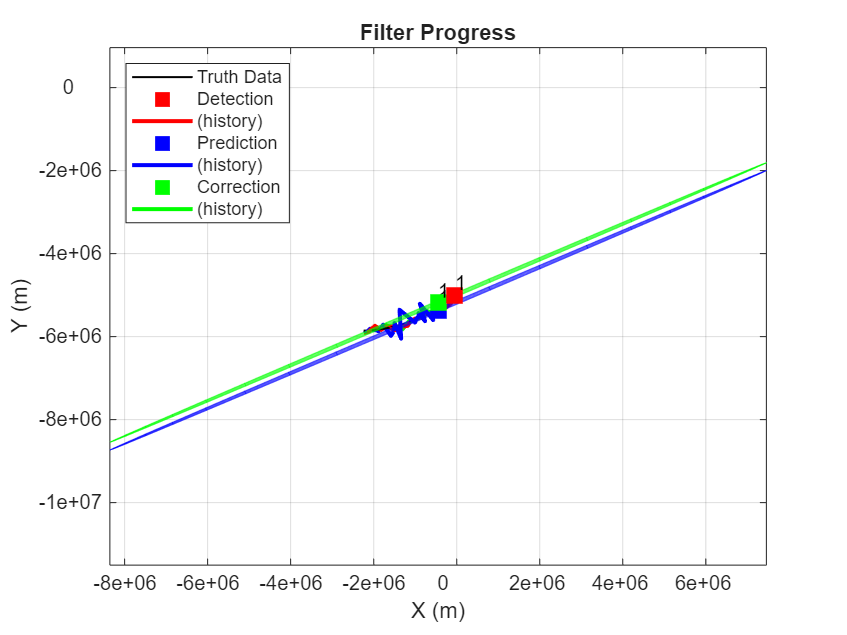

mahalanobisDist = helperRunDataLoop(detPos,truthPos,filter,time,objDet{1}.MeasurementNoise);

 Plot Mahalanobis Distance

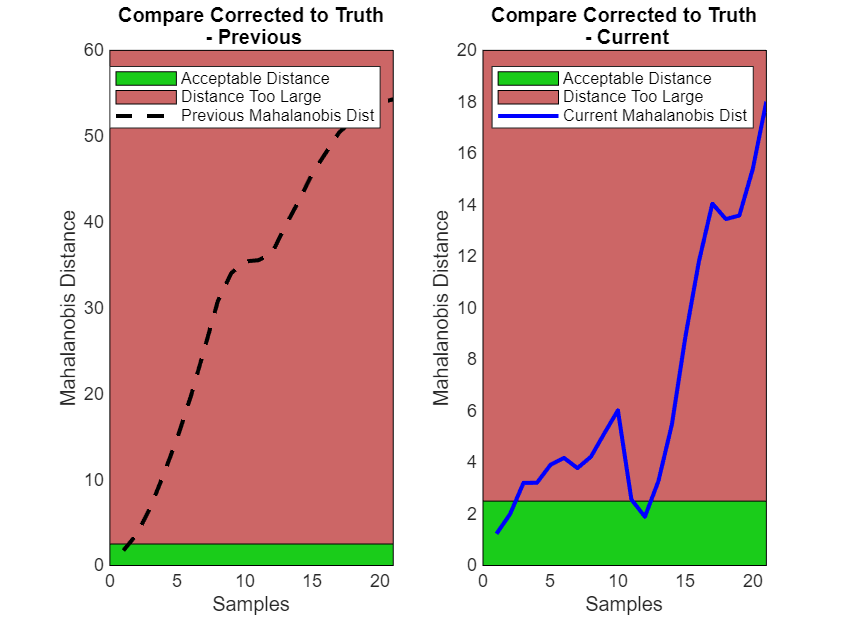

plotMahalanobisDist(mahalanobisDist,mahDist1);

**Leverage a Tuned Filter to Estimate the State**

Coding Directions

Leverage the "tunedInitFcn" created by leveraging the "trackingFilterTuner" to tune the parameters of our "initcaekf" filter. This can be accomplished by passing the "initialDetection" variable to the function "tunedInitFcn" and storing the output in the variable "filter".

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER CODES THIS:
% type "doc trackingFilterTuner" in the Command Window to find the documentation
% page for this function and look for the "Customize Tunable Properties and
% Tune Tracking Filter" Example

filter = tunedInitFcn_CT(initialDetection);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Pass the initial state to the filter
filter.State = initialState;

Run through data loop:

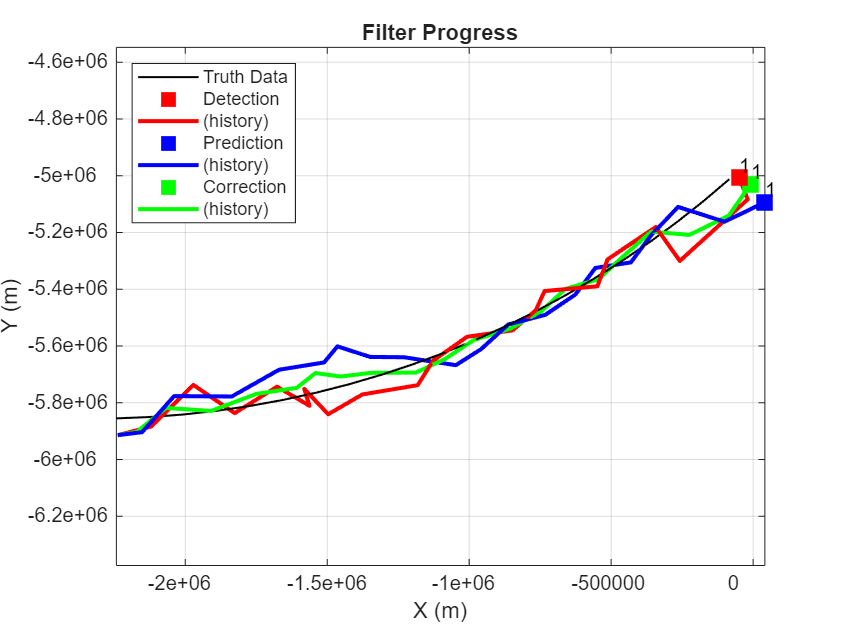

mahalanobisDist = helperRunDataLoop(detPos,truthPos,filter,time,objDet{1}.MeasurementNoise);

Plot Mahalanobis Distance

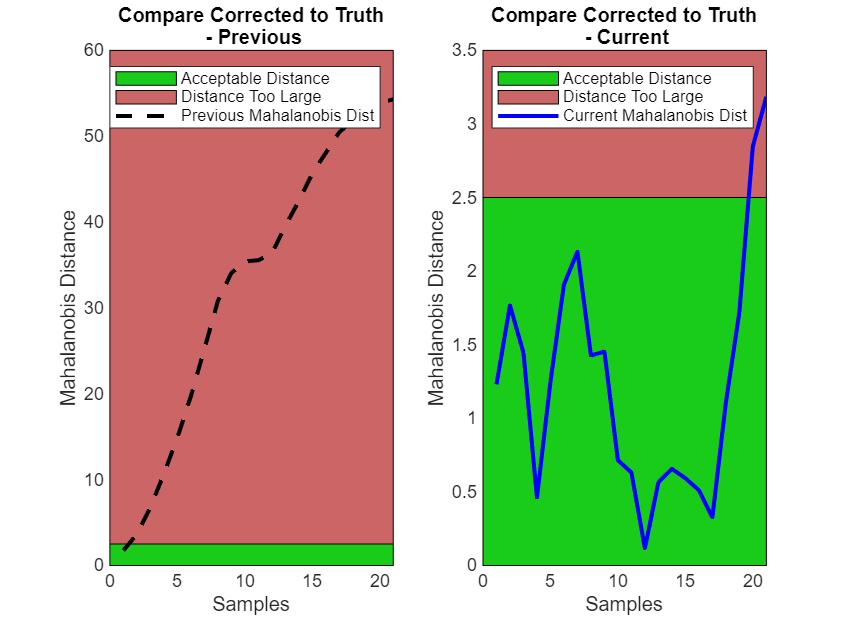

plotMahalanobisDist(mahalanobisDist,mahDist1);

# **Takeaways**

Once we have setup our estimation filter to match the motion of the targets within our scenario, we see that our predicted and corrected locations are close to the detections AND that our Mahalanobis distances are around 1 Standard Deviation. In general, it is critical that the estimation filter is adjusted to match the expected dynamics of the targets that you are tracking.

## **HELPER FUNCTIONS**

**helperRunDataLoop**

function mahCorrTruth = helperRunDataLoop(detPos,truthPos,filter,time,detectionMeasurementNoise)

tp = theaterPlot();

% Create Plotters
trajPlotter = trajectoryPlotter(tp,'DisplayName','Truth Data','LineWidth',1,'LineStyle','-','Color','k');
%detPlotter = detectionPlotter(tp,'HistoryDepth',1e3,'DisplayName','Detection','MarkerSize',10,'MarkerFaceColor','r');
detPlotter = trackPlotter(tp,'HistoryDepth',1e3,'DisplayName','Detection','MarkerSize',10,'MarkerFaceColor','r','MarkerEdgeColor','r','ConnectHistory','on');
predPlotter = trackPlotter(tp,'HistoryDepth',1e3,'DisplayName','Prediction','MarkerSize',10,'MarkerFaceColor','b','MarkerEdgeColor','b','ConnectHistory','on');
corrPlotter = trackPlotter(tp,'HistoryDepth',1e3,'DisplayName','Correction','MarkerSize',10,'MarkerFaceColor','g','MarkerEdgeColor','g','ConnectHistory','on');

% Plot Truth As Trajectory
plotTrajectory(trajPlotter,{truthPos'})
grid on, box on; legend(gca,'Location','northwest')

% Extend Measurement noise:
measurementNoise3D = repmat(detectionMeasurementNoise,[1,1,height(detPos')]);

% Plot Detections in a "as sensor detects target" fashion
deltaT = diff(time);
deltaT = deltaT(1);
for n = 1:length(time)
    % Plot Position of Current Detection iteration 
    % plotDetection(detPlotter,detPos',measurementNoise3D) % Adds ellipses on Detections
    plotTrack(detPlotter,detPos(:,n)',string(1))

    % Make state prediction using predict method of the filter
    [pstates(n,:), pCov(:,:,n)]  = predict(filter,deltaT);

    % Correct estimate using detections and the correct method of the filter
    [cstates(n,:), cCov(:,:,n)] = correct(filter, detPos(:,n)');
    
    % Pause during loop to watch tracker progress during visualization
    pause(0.1)
end

% Pull out position only from prediction and correction, for plotting
% Constant Velocity
% pstatesPos = pstates(:,[1 3 5]);
% cstatesPos = cstates(:,[1 3 5]);

% Constant Turn
% The state of the filter is defined as [x; vx; y; vy; theta; z; vz],
pstatesPos = pstates(:,[1 3 6]); pstatesVelo = pstates(:,[2 4 7]); posPCov = pCov([2 4 7],[2 4 7],:);
cstatesPos = cstates(:,[1 3 6]); cstatesVelo = cstates(:,[2 4 7]); posCCov = pCov([2 4 7],[2 4 7],:);

% % Constant Acceleration
% % The state of the filter is defined as [x; vx; ax; y; vy; ay; z; vz; az], in which x, y, z are the position coordinates, vx, vy, vz are the corresponding velocities, and ax, ay, az are the corresponding accelerations.
% pstatesPos = pstates(:,[1 4 7]); pstatesVelo = pstates(:,[2 5 8]); posPCov = pCov([2 5 8],[2 5 8],:);
% cstatesPos = cstates(:,[1 4 7]); cstatesVelo = cstates(:,[2 5 8]); posCCov = pCov([2 5 8],[2 5 8],:);

% Plot Prediction and Correction, then add Title and Rotate to 2D view
for j = 1:size(pstatesPos,1)
    plotTrack(predPlotter,pstatesPos(j,:),posPCov(:,:,j),string(1)) % Plot Prediction
    plotTrack(corrPlotter,cstatesPos(j,:),posCCov(:,:,j),string(1)) % Plot Correction

    % Pause during loop to watch tracker progress during visualization
    pause(0.1)
end
title('Filter Progress'); hold on; grid on; axis equal; % Add Title
view([0 90.00]) % Rotate to 2D view

% Calculate Mahalanobis Distance - Position-Only (posnees) form:
% Corrected versus Truth
mahCorrTruth = calcMahalanobisDist(truthPos,cstates,cCov,time);

end

**calcMahalanobisDist**

function mahCorrTruth = calcMahalanobisDist(truthPos,cstates,cCov,time)
% Calculate Mahalanobis Distance - Position-Only (posnees) form:
% Corrected versus Truth
truthData = truthPos([1 2],:); % Please delete when final dataset used

for i = 1:length(time)
    % % Const Velo
    % e = cstates(i,[1 3])' - truthData(:,i);
    % P = cCov([1 3],[1 3],i);
    % mahCorrTruth(i) = sqrt(e'/P*e);

    % Const Turn - 3D
    e = cstates(i,[1 3 6])' - truthPos(:,i);
    P = cCov([1 3 6],[1 3 6],i);
    mahCorrTruth(i) = sqrt(e'/P*e);
    
    % % Const Acc - 2D
    % e = cstates(i,[1 4])' - truthData(:,i);
    % P = cCov([1 4],[1 4],i);
    % mahCorrTruth(i) = sqrt(e'/P*e);

    % % Const Acc - 3D
    % e = cstates(i,[1 4 7])' - truthPos(:,i);
    % P = cCov([1 4 7],[1 4 7],i);
    % mahCorrTruth(i) = sqrt(e'/P*e);
end
end

**plotMahalanobisDist**

function [d2, figHandle]= plotMahalanobisDist(d2,prevD2)

% Instead, plot them as subplots next to one another
figHandle = figure; subplot(1,2,1); hold on; plot(prevD2,'LineWidth',2,'Color','k','LineStyle','--');
ybars = [0 2.5];
ybarsBad = [2.5 max(ylim)];
minX  = min(xlim); maxX = max(xlim);
cla;

patch([minX maxX maxX minX], [ybars(1) ybars(1), ybars(2) ybars(2)], [0.1 0.8 0.1]) % Green, good
patch([minX maxX maxX minX], [ybarsBad(1) ybarsBad(1), ybarsBad(2) ybarsBad(2)], [0.8 0.4 0.4]) % Red, bad

% Repeated plot call to prevent patch from hiding
plot(prevD2,'LineWidth',2,'Color','k','LineStyle','--');
xlabel('Samples')
ylabel('Mahalanobis Distance')
title(sprintf('Compare Corrected to Truth\n - Previous'))

% Create Legend
legend({'Acceptable Distance','Distance Too Large','Previous Mahalanobis Dist',})

% SECOND SUBPLOT
subplot(1,2,2); hold on; plot(d2,'LineWidth',2,'Color','b');
minX  = min(xlim); maxX = max(xlim);
ybarsBad = [2.5 max(ylim)];
cla;

patch([minX maxX maxX minX], [ybars(1) ybars(1), ybars(2) ybars(2)], [0.1 0.8 0.1]) % Green, good
patch([minX maxX maxX minX], [ybarsBad(1) ybarsBad(1), ybarsBad(2) ybarsBad(2)], [0.8 0.4 0.4]) % Red, bad

% Repeated plot call to prevent patch from hiding
plot(d2,'LineWidth',2,'Color','b');
xlabel('Samples')
ylabel('Mahalanobis Distance')
title(sprintf('Compare Corrected to Truth\n - Current'))

% Create Legend
legend({'Acceptable Distance','Distance Too Large','Current Mahalanobis Dist',})

end